% Generate I and Q Baseband Data
numberOfSymbols = 8;
bitsPerSymbol = 2;
M = 2^bitsPerSymbol;
idxI = randi([1, bitsPerSymbol],[1, numberOfSymbols]);
idxQ = randi([1, bitsPerSymbol],[1, numberOfSymbols]);

numberOfLevels = bitsPerSymbol;
levels = 1:2:numberOfLevels-1;
levels = [-flip(levels), levels];
numberOfLevels = length(levels);

assert(numberOfLevels == bitsPerSymbol, 'Error: Number of Levels != Number of Bits/ Symbol')

symbolsI = zeros(size(idxI));
symbolsQ = zeros(size(idxQ));
for k = 1:length(idxI)
    symbolsI(k) = levels(idxI(k));
    symbolsQ(k) = levels(idxQ(k));
end
disp('Symbols Created')

Symbols Created


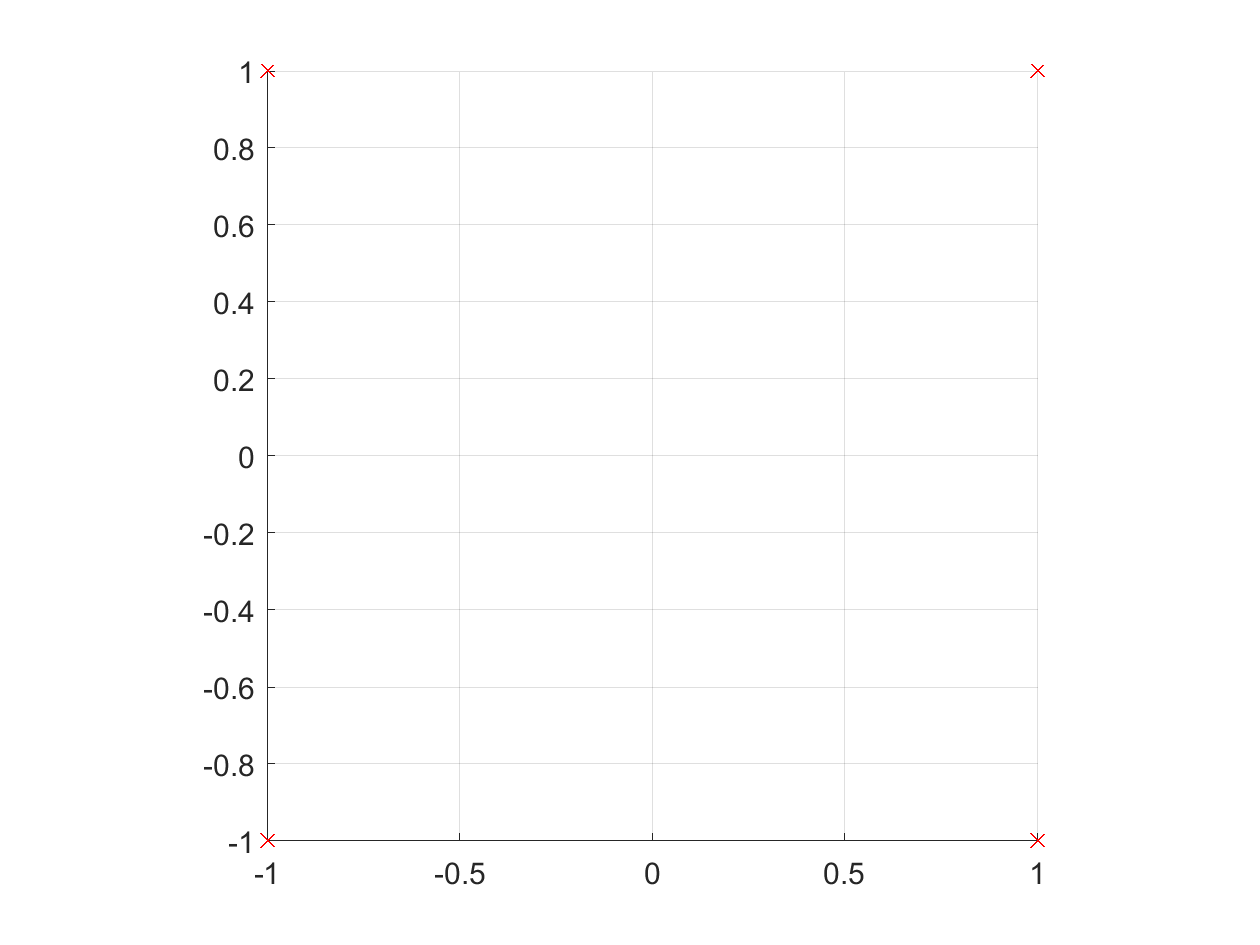

scatter(symbolsI, symbolsQ, 'xr')
grid on
axis square

% Signal Params
bitRate = 1;
symbolRate = bitRate/bitsPerSymbol;

carrierFrequency = 10;
samplesPerCycle = 2^7; % Needs to be power of 2
% samplesPerSymbol = samplesPerCycle*carrierFrequency/symbolRate;

Fs = samplesPerCycle*carrierFrequency;
Ts = 1/Fs;

A = 10;
% L = samplesPerCycle*numberOfSymbols*carrierFrequency/symbolRate;
L = numberOfSymbols*samplesPerCycle;
timeRF = Ts*(0:L-1);
bitTime = 1/bitRate;
symbolTime = 1/symbolRate;
disp('Time Vectors Created')

Time Vectors Created


% Generate Upsampled Bits
zohRF = ones([1 samplesPerCycle]);

symbolsUpsampledI = upsample(symbolsI, samplesPerSymbol);
x_MPAM_I = convfft(symbolsUpsampledI, zohBB);
x_MPAM_I = x_MPAM_I(1:LBB)';

symbolsUpsampledQ = upsample(symbolsQ, samplesPerSymbol);
x_MPAM_Q = convfft(symbolsUpsampledQ, zohBB);
x_MPAM_Q = x_MPAM_Q(1:LBB)';
disp('MPAM Data Created')

MPAM Data Created



% scatter(x_MPAM_I, x_MPAM_Q)

% Up Conversion LO
LO_I = A*cos(2*pi*carrierFrequency*timeRF);
LO_Q = -A*sin(2*pi*carrierFrequency*timeRF);
% close all
% stem(LO_I)
% hold on
% stem(LO_Q)
% xlim([0, 0.001e5])

% Upsample to match RF
x_MPAM_I_RF = upsample(x_MPAM_I, LRF/LBB);
x_MPAM_I_RF = convfft(x_MPAM_I_RF, zohRF);
x_MPAM_I_RF = x_MPAM_I_RF(1:LRF)';

x_MPAM_Q_RF = upsample(x_MPAM_Q, LRF/LBB);
x_MPAM_Q_RF = convfft(x_MPAM_Q_RF, zohRF);
x_MPAM_Q_RF = x_MPAM_Q_RF(1:LRF)';
disp('MPAM Upsampling Done')

MPAM Upsampling Done


% scatter(x_MPAM_I_RF, x_MPAM_Q_RF)

% Up Convert to RF
x_QAM_I = LO_I.*x_MPAM_I_RF;
x_QAM_Q = LO_Q.*x_MPAM_Q_RF;

% PSD of I/Q RF Signal
% periodogram(x_QAM_I,rectwin(length(x_QAM_I)),length(x_QAM_I),FsRF, 'onesided')
% hold on
% periodogram(x_QAM_Q,rectwin(length(x_QAM_Q)),length(x_QAM_Q),FsRF, 'onesided')

% Create the RF QAM Signal
x_QAM = x_QAM_I + x_QAM_Q;
span = symbolRate;
x_QAM_Filtered = bandpass(x_QAM, [carrierFrequency - span, carrierFrequency + span], Fs);
disp('QAM Signal Created')

QAM Signal Created



% PSD of QAM RF Signal
% periodogram(x_QAM,rectwin(length(x_QAM)),length(x_QAM),FsRF, 'onesided')
% periodogram(x_QAM_Filtered,rectwin(length(x_QAM_Filtered)),length(x_QAM_Filtered),FsRF, 'onesided')

% Simulate Noisy Channel
% variance = 1/(Ts*(10^(SNRdB/10)));
variance = 0;
noise = sqrt(variance)*randn(size(timeRF));

% Recieved Signal
sRX = x_QAM_Filtered + noise;
% periodogram(sRX,rectwin(length(sRX)),length(sRX),Fs, 'onesided')

% Calculate SNR
BW = obw(sRX, Fs);
SNRa = var(x_QAM_Filtered)/var(noise);
SNRd = SNRa*BW/bitRate;
disp('Noisy QAM Signal Created')

Noisy QAM Signal Created


fprintf('Analog SNR is %.2f dB\n', 10*log10(SNRa))

Analog SNR is Inf dB


fprintf('Digital SNR is %.2f dB\n', 10*log10(SNRd))

Digital SNR is Inf dB


fprintf('Signal Bandwidth is %.2f MHz\n', BW/1e6)

Signal Bandwidth is 121.01 MHz


% Split Data into I and Q Channels
s_I = sRX.*LO_I;
s_Q = sRX.*LO_Q;
% periodogram(s_I,rectwin(length(s_I)),length(s_I),FsRF, 'onesided')
% periodogram(s_Q,rectwin(length(s_Q)),length(s_Q),FsRF, 'onesided')

s_I3 = lowpass(s_I, carrierFrequency, Fs); 
s_Q3 = lowpass(s_Q, carrierFrequency, Fs); 
% periodogram(s_I3,rectwin(length(s_I3)),length(s_I3),FsRF, 'onesided')
% periodogram(s_Q3,rectwin(length(s_Q3)),length(s_Q3),FsRF, 'onesided')
% scatter(s_I3, s_Q3)
disp('RX Downconvert Done')

RX Downconvert Done


% Downsample to BB
s_I2 = downsample(s_I3, LRF/LBB);
s_Q2 = downsample(s_Q3, LRF/LBB);
% periodogram(s_I2,rectwin(length(s_I2)),length(s_I2),FsBB, 'onesided')
% periodogram(s_Q2,rectwin(length(s_Q2)),length(s_Q2),FsBB, 'onesided')
disp('RX Downsample Done')

RX Downsample Done


% scatter(s_I2, s_Q2)

% Generate Matched Filter Impulse Response
% Rect Pulse Shape
rect = @(t, T) ...
    (ceil(heaviside(t)) - ceil(heaviside(t - T*ones(size(t)))));
h = rect(timeBB, symbolTime);

% Apply Matched Filter to Rx Sequence
% Regular Conv is slow (O(n^2))
% yI = conv(s_I2, h);
% yQ = conv(s_Q2, h);
% yI = convfft(s_I2, h)';
% yQ = convfft(s_Q2, h)';
% 
% yI2 = yI(1:LBB-1);
% yQ2 = yQ(1:LBB-1);
% yI2 = [yI2(1), yI2];
% yQ2 = [yQ2(1), yQ2];
% 
% % Normalize Sequence to have Power of 1
% yI2 = yI2/sqrt(var(yI2));
% yQ2 = yQ2/sqrt(var(yQ2));

% yI3 = movmean(yI2, 40);
% yQ3 = movmean(yQ2, 40);
% disp('Matched Filter Applied')

% [RxyI, tau1] = xcorr(x_MPAM_I, yI2);
% [RxyQ, tau2] = xcorr(x_MPAM_Q, yQ2);
% plot(tau1, RxyI)
% plot(tau2, RxyQ)

% Decimate Rx Signal to contain 1 sample per bit
% mI = zeros([1, numberOfSymbols]);
% mQ = zeros([1, numberOfSymbols]);
% for k = 1:numberOfSymbols  
%     for tau = (k-1)*samplesPerSymbol+1:k*samplesPerSymbol
%         if mod(timeBB(tau), symbolTime) == 0
%             mI(k) = yI2(tau);
%             mQ(k) = yQ2(tau);
%         end
%     end
% end
% mI = mI - mean(mI);
% mQ = mQ - mean(mQ);

mI = zeros([1, numberOfSymbols]);
mQ = zeros([1, numberOfSymbols]);
for k = 1:numberOfSymbols
    startIdx = (k-1)*samplesPerSymbol+1;
    endIdx = k*samplesPerSymbol;
    for w = startIdx:endIdx
        mI(k) = mI(k) + s_I2(w);
        mQ(k) = mQ(k) + s_Q2(w);           
    end
end
disp('RX Decimate Done')
% [RmI, tauI] = xcorr(symbolsI, mI);
% plot(tauI, RmI)
% [RmQ, tauQ] = xcorr(symbolsQ, mQ);
% plot(tauQ, RmQ)

% Plot Signal Constellation
% close all
% scatter(mI, mQ)
% xlabel('In Phase Channel')
% ylabel('Quadrature Phase Channel')
% grid on
% axis square

% Decode back into symbols
% Find the thresholds
% mIHist = histcounts(mI, 100);
% VI = mIHist.Values;
% EI = mIHist.BinEdges;
[VI, EI] = histcounts(mI);
LI = islocalmax(VI);
leftI = EI(LI);
rightI = EI([false LI]);
centerI = (leftI + rightI)/2;
% hold on
% plot(centerI, VI(LI), 'o')

% Remove any False Positives
peaksI = VI(LI);

[valI, idxI] = find(peaksI < mean(peaksI) - 3*sqrt(var(peaksI)));
try
    peaksI(idxI) = [];
    centerI(idxI) = [];  
catch ME
    disp('No Close Points Found in Peaks I Array')
end


centerDiffI = diff(centerI);
[valI, idxI] = find(centerDiffI < mean(centerDiffI) - sqrt(var(centerDiffI)));
try
    peaksI(idxI) = [];
    centerI(idxI) = [];  
catch ME
    disp('No Close Points Found in Center I Array') 
end

% Check to make sure Number of Peaks = Number of Levels
assert(length(peaksI) == numberOfLevels, 'Error: Incorrect Number of Peaks for I channel')
assert(length(centerI) == numberOfLevels, 'Error: Incorrect Number of Peaks for I channel')
assert(max(abs(peaksI - mean(peaksI))) <= 3*sqrt(var(peaksI)), 'Error: I Channel Peak Levels are Weird')

% mQHist = histcounts(mQ, 100);
% VQ = mQHist.Values;
% EQ = mQHist.BinEdges;
[VQ, EQ] = histcounts(mQ);
LQ = islocalmax(VQ);
leftQ = EQ(LQ);
rightQ = EQ([false LQ]);
centerQ = (leftQ + rightQ)/2;
% hold on
% plot(centerQ, VQ(LQ), 'o')

% Remove any False Positives
peaksQ = VQ(LQ);

[valQ, idxQ] = find(peaksQ < mean(peaksQ) - 3*sqrt(var(peaksQ)));
try
    peaksQ(idxQ) = [];
    centerQ(idxQ) = [];  
catch ME
    disp('No Close Points Found in Peaks Q Array')
end

centerDiffQ = diff(centerQ);
[valQ, idxQ] = find(centerDiffQ < mean(centerDiffQ) - 2*sqrt(var(centerDiffQ)));
try
    peaksQ(idxQ) = [];
    centerQ(idxQ) = [];  
catch ME
    disp('No Close Points Found in Center I Array') 
end


% Check to make sure Number of Peaks = Number of Levels
assert(length(peaksQ) == numberOfLevels, 'Error: Incorrect Number of Peaks for Q channel')
assert(length(centerQ) == numberOfLevels, 'Error: Incorrect Number of Peaks for Q channel')
assert(max(abs(peaksQ - mean(peaksQ))) <= 3*sqrt(var(peaksQ)), 'Error: Q Channel Peak Levels are Weird')

% scatter(centerI, peaksI)
% hold on
% scatter(centerQ, peaksQ)

% Find the (sub) Optimum Thresholds 
distanceI = mean(diff(centerI));
thresI = (1:numberOfLevels/2)*distanceI;
thresI(end) = 10*thresI(end); % account for unbounded edge points
thresI = [-flip(thresI), 0, thresI];

distanceQ = mean(diff(centerQ));
thresQ = (1:numberOfLevels/2-1)*distanceQ;
thresQ(end) = 10*thresQ(end); % account for unbounded edge points
thresQ = [-flip(thresQ), 0, thresQ];
disp('RX Thresholds Found')

% Now decode based on the thresholds
symbolsRxI = zeros(size(symbolsI));
symbolsRxQ = zeros(size(symbolsQ));
for k = 1:numberOfLevels
    [tempVal, tempIdx] = find(mI > thresI(k) & mI < thresI(k+1));
    symbolsRxI(tempIdx) = levels(k);
%     subplot(2,1,1)
%     histogram(mI(tempIdx), 30)
%     hold on
      
    [tempVal, tempIdx] = find(mQ > thresI(k) & mQ < thresI(k+1));
    symbolsRxQ(tempIdx) = levels(k);
%     subplot(2,1,2)
%     histogram(mQ(tempIdx), 30)
%     hold on
end
disp('RX Decode Done')

% [RxsI, tauI] = xcorr(symbolsI, symbolsRxI);
% plot(tauI, RxsI)
% [RxsQ, tauQ] = xcorr(symbolsQ, symbolsRxQ);
% plot(tauQ, RxsQ)

% Find Bit Error Rate

% plot(symbolsRxQ(2:end) - symbolsQ(1:end-1))
% plot(symbolsRxI(2:end) - symbolsI(1:end-1))

% iErrors = symbolsRxI(2:end) - symbolsI(1:end-1);
iErrors = symbolsRxI - symbolsI;
iErrors = abs(iErrors);
iErrors(iErrors > 0.5) = 1;
iErrors(iErrors <= 0.5) = 0;

numberOfIErrors = sum(iErrors);
berI = numberOfIErrors/numberOfSymbols

% qErrors = symbolsRxQ(2:end) - symbolsQ(1:end-1);
qErrors = symbolsRxQ - symbolsQ;
qErrors = abs(qErrors);
qErrors(qErrors > 0.5) = 1;
qErrors(qErrors <= 0.5) = 0;

numberOfQErrors = sum(qErrors);
berQ = numberOfQErrors/numberOfSymbols
disp('Bit Error Rates Found')